# Electrical and Mechanical Relationships

3.1 Flux Linkage and Inducatnace 


i= ? ; % current 
R = ?; % reluctance seen by the MMF source
N = ?; % the turns of winding

phi = N*i/R;


% total flux 

lamdba = N * phi;


L = lamdba / i; % inductance 



Mutual Inductance 


$$\phi_! =\phi_{11} +\phi_{12}$$



$$\phi_2 =\phi_{22} +\phi_{21}$$


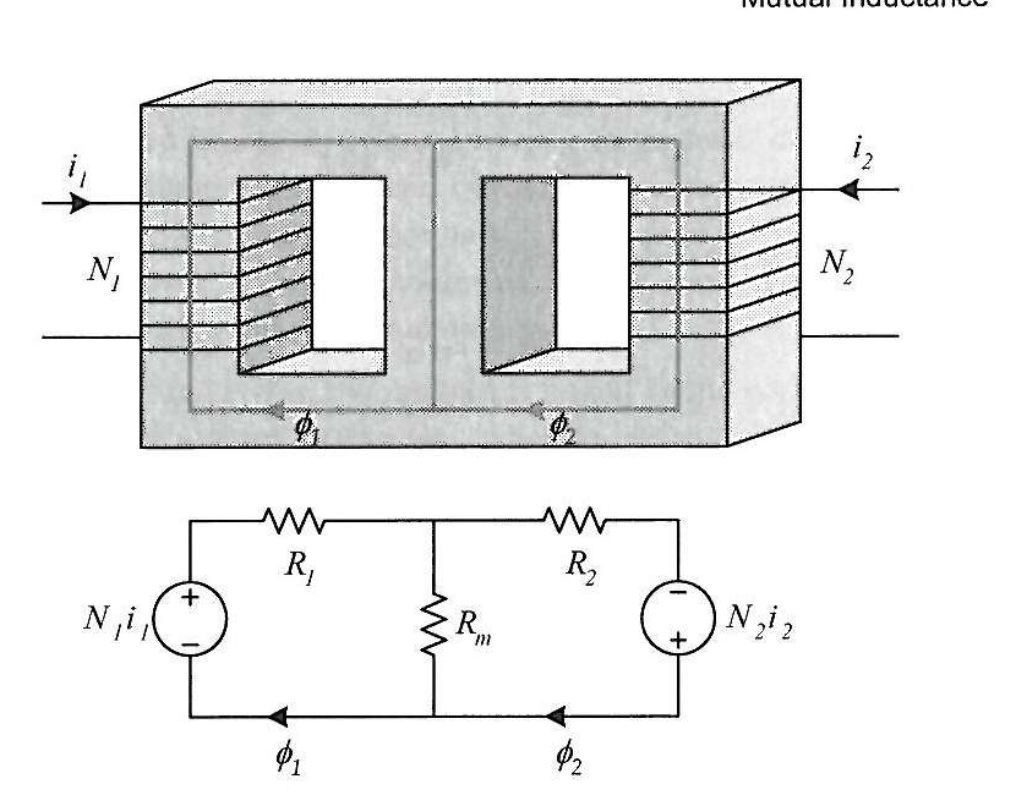

R_1 = ?; 
R_2 = ?;
R_m = ?;
N_1 = ?;
N_2 = ?;
i_1 = ?;
i_2 = ?;



term_1 = (R_2* R_m/(R_2 + R_m));
phi_11 = N_1 * i_1 / (R_1 + term_1);

term_2 = (R_1* R_m/(R_1 + R_m));
phi_22 = N_2 * i_2 / (R_2 + term_2);

phi_12 = phi_22 * R_m/(R_1 + R_m);

phi_21 = phi_11 * R_m/(R_2 + R_m);


phi_1 = phi_11 + phi_12;
phi_2 = phi_22 + phi_21;


lamdba_1 = N_1* phi_1;
lamdba_2 = N_2 * phi_2;

## Mutual Flux due to a permanent Magnet


phi_1 = N*i / (R+ R_m); % the flux linking the coil ude ot the coil current
phi_m = R_m * phi_r / (R+ R_m); % the flux linking the coil due to the magnet
phi = phi_1 + phi_m;

lamdba = N * phi;

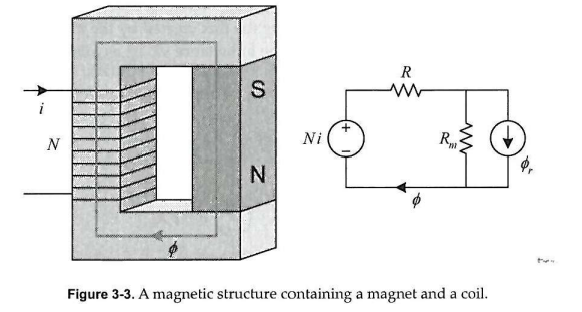

## Faraday's Law


$$e=\frac{d\lambda }{\textrm{dt}}$$
 

voltage e induced 

## Lenz's Law

govern the direction of coltage 

% combine both laws 

L = ?; % self inductance 
i= ? ; % current 


e = L*di_dt + i * dL_dt; % 
% L* di+dt is the transformer voltage 
% second term is the speed voltage or back EMF

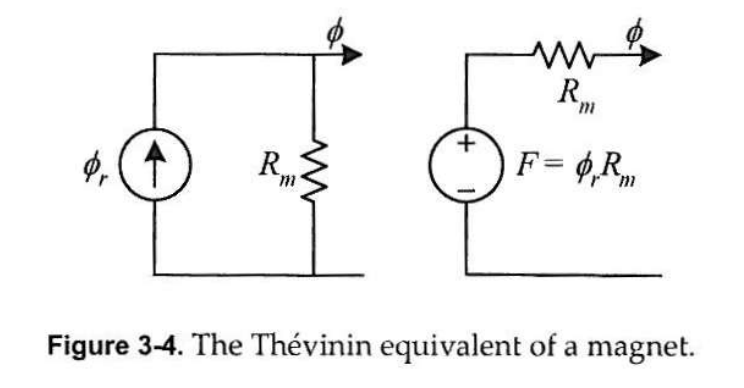

if mode == "linear"
    v = ? ; % dx/dt
    dL_dt = dL_dx * v ;
elseif mode == "rotational"
% or rotational system
    
    w = ?;% angx
    dL_dt = dL_dtheta * w ;
end
e = L*di_dt + i * dL_dt; % 


e = L*di_dt + i * dL_dt + N * dphi/dt + phi * dN_dt; 
% N *dphi/dt the last terms takes into account situation where the magnet moves reltaive to the coil cuasing a change in the amount of manget flux linekd to coil
% phi * dN/dt te number of terns linked by the magnet flux varies


## Energy and Coenergy


syms t i(t) lambda(t)

% Define lambda(t) and i(t)
lambda(t) = 5*t^2 + 2*t;    % Example flux linkage
i(t) = diff(lambda(t), t);  % Current as derivative (if lambda known first)

% Compute dλ/dt
dlambda_dt = diff(lambda, t);

% Power
p = i(t) * dlambda_dt;

% Define time T
T = 2;
W = int(p, t, 0, T);   % Energy

% Co-energy: requires lambda as function of i
% Let’s assume linear lambda(i): lambda = L*i, so invertible
syms i_sym
L = 10;
lambda_i = L * i_sym;
W_c = int(lambda_i, i_sym, 0, i(t));   % Co-energy




$$P=\mu \frac{A}{l}$$



$$\lambda =N\phi$$



$$L=N^2 P$$



$$F=\mathrm{Ni}$$


energy and coenergy can be written as 


$$W=\frac{\phi^2 }{2P}$$



$$W_c =\frac{1}{2}{\mathrm{PF}}^2$$


    can also find the density with W/ volumn

% energy and coenergy can be written as 






% Energy and Coenergy in Doubly-Excited System in fig 1
lamdba1 = ?;
dlamdba1_dt = diff(lamdba1, t);

lamdba2 = ?;
dlamdba2_dt = diff(lamdba2, t);
p = i_1 * dlamdba1_dt + i_2 * dlamdba2_dt;
T = 4;
W = int(p, t, 0, T); 


Fundamental implication 

 larger diameter -> larger torque  but doesnt increase ratioof output power to volume

larger diameter -> larger radius -> increase the torque to inertia ratio of a motor ( resistance to cahgne in motion due to an object's mass)

limitation :

    - physical space limitations dictated by a particualar application

- volume

- mass

- inertia

to increase power given diameter , 

need to increase speed :

- using some speed reduction :

-     but speed reduction componenets also add in volume , mass ,inertia ,cost , frictional losses and reduced relaiblity 

need to increase the force density acting on the rotor :

- incerasing the electrical and magnetic operating points of the motor

-     increase the current supplying

-     add ohmic loss I^2 R to the system

- increase magnetic 

-     use higher performance magnet material , or specialised motor construction to focus or concentrate flux into afir gap

in doubly excited system

$p=i_{1\;} \frac{\partial \lambda_1 }{\partial t}+i_2 \frac{\partial \lambda_2 }{\partial t}$ ------(1)

$W=\frac{\lambda_{11}^2 }{2L_1 }+\frac{\lambda_{22}^2 }{2L_2 }+\frac{\lambda_{12} \lambda_{21} }{L_{12} }$ -------------(2)energy 

$W_c =\frac{1}{2\;}L_1 i_1^2 +\frac{1}{2\;}L_2 i_2^2 +i_1 i_2 L_{12}$----------(3) coenergy

Coenergy in the presence of a permanet Magnet 

$W_c =\frac{1}{2}*{\mathrm{Li}}^2 +\frac{1}{2}\left(R+R_m \right)\phi_m^2 +\mathrm{Ni}\phi_m$ --------(4)

fist term is the coenergy stroed in the self inductance (not desired)

second term is the coenergy stored due to the magnet alone

third is mutual indcutance (desired)

## Torque from a macroscpic viewpoint

${\mathrm{dW}}_e =\mathrm{dW}+{\mathrm{dW}}_m$ ---------(5)

the change in electrical , magnetic and mechanical 

and torque

$T=\frac{-\partial W}{\partial \Theta }|$lamdb - constant -------(6)

or 

$T=\frac{\partial W_c }{\partial \Theta }$| i = constant ---------------(7)

applying (3) with (7):


$$T=\frac{1}{2\;}i_1^{2\;} \frac{\partial L}{\partial \Theta }+\frac{1}{\;2}i_2^{2\;} \frac{\partial L}{\partial \Theta }+i_{1\;} i_2 \frac{\partial L_{12} }{\partial \Theta }$$


if i_2 = 0 , ( singly excited system ) only the first term 

the torque prdocued is a function of the square of the applied current and not related to sign (reluctance toruq)

apply (4) with (7)


$$T=\frac{1}{2}i^{2\;} \frac{\partial L}{\partial \Theta }-\frac{1}{2}\phi^2 \frac{\partial R}{\partial \Theta }+\mathrm{Ni}\frac{\partial \phi }{\partial \Theta }$$


the reluctane torque associated with the coil and magnet respectively 

the thid term is the alignent toruqe due to the mutual flux phi linking the magnet to the coil ( desride)

the second term is the cogging torque 